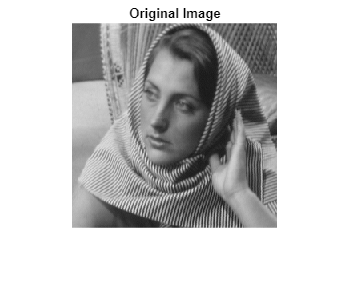

% Step 1: Preprocessing
imageFile = 'barbara256.png';
originalImg = imread(imageFile);
if size(originalImg, 3) == 3
    originalImg = rgb2gray(originalImg); % Convert to grayscale if RGB
end
originalImg = double(originalImg); % Convert to double for processing
[rows, cols] = size(originalImg);

% Display the original image
figure; imshow(uint8(originalImg)); title('Original Image');

%% Step 3: Rectangular Subdivision
% Function to recursively subdivide and select points based on MSE threshold
function [selectedPoints, binaryTree] = recursiveSubdivision(img, threshold, depth, maxDepth, binaryTree)
    [h, w] = size(img);
    midRow = round(h / 2);
    midCol = round(w / 2);
    
    % 0: Use EED to reconstruct the rectangle to be subdivided
    borderPoints = [1, 1; 1, midCol; 1,w; 
                    midRow,1; midRow,w;
                    h, 1; h, midCol; h, w];

     % Initialize an image for EED with zeros
    subdividedImg = zeros(size(img));

    % Place the intensity values of the selected points
    for i = 1:size(borderPoints, 1)
        row = borderPoints(i, 1); % Row coordinate of the point
        col = borderPoints(i, 2); % Column coordinate of the point
        subdividedImg(row, col) = img(row, col); % Copy intensity value
    end

    % Example usage
    lambda = 20;
    sigma = 0.8;
    numIterations = 10;
    diffusedImg = EED(subdividedImg, borderPoints, lambda, sigma, numIterations);

    mseError = mean((diffusedImg(:) - img(:)).^2); %mseError = mean((img(:) - mean(img(:))).^2);

    % 1: Base case: stop subdivision if max depth reached or below error threshold

    if depth > maxDepth || mseError <= threshold
        selectedPoints = borderPoints; % Corners as default points
        binaryTree = [binaryTree, 0];
        return;
    end
    binaryTree = [binaryTree, 1];



    subImgs = {
        img(1:midRow, 1:midCol), img(1:midRow, midCol+1:end);
        img(midRow+1:end, 1:midCol), img(midRow+1:end, midCol+1:end)
    };
    
    % Recursively process each sub-region
    selectedPoints = [];
    for i = 1:2
        for j = 1:2
            [subPoints, binaryTree] = recursiveSubdivision(subImgs{i, j}, threshold, depth + 1, maxDepth, binaryTree);
            subPoints(:, 1) = subPoints(:, 1) + (i-1) * midRow;
            subPoints(:, 2) = subPoints(:, 2) + (j-1) * midCol;
            selectedPoints = [selectedPoints; subPoints]; %#ok<AGROW>
        end
    end
end

% Subdivision parameters
threshold = 150; % MSE threshold
maxDepth = 10;    % Maximum recursion depth
[selectedPoints, binaryTree] = recursiveSubdivision(originalImg, threshold, 0, maxDepth, []);
disp(size(selectedPoints));

   128     2



disp(binaryTree);

     1     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0



%% Step 3: Rectangular Subdivision
% Function to recursively subdivide and select points based on MSE threshold
function [selectedPoints, binaryTree] = REED(img, threshold, depth, maxDepth, binaryTree)
    [h, w] = size(img);
    midRow = round(h / 2);
    midCol = round(w / 2);
    
    % 0: Define border points
    borderPoints = [1, 1; 1, midCol; 1,w; 
                    midRow,1; midRow,w;
                    h, 1; h, midCol; h, w];

     % Initialize an image for EED with zeros
    subdividedImg = zeros(size(img));

    % Place the intensity values of the selected points
    for i = 1:size(borderPoints, 1)
        row = borderPoints(i, 1); % Row coordinate of the point
        col = borderPoints(i, 2); % Column coordinate of the point
        subdividedImg(row, col) = img(row, col); % Copy intensity value
    end

    % 1: Reconstruct to decide subdivision
    lambda = 20;
    sigma = 0.8;
    numIterations = 10;
    diffusedImg = EED(subdividedImg, borderPoints, lambda, sigma, numIterations);
    mseError = mean((diffusedImg(:) - img(:)).^2); 

    % 2: Base case: stop subdivision if max depth reached or below error threshold
    if depth >= maxDepth || mseError <= threshold
        selectedPoints = borderPoints; % Corners as default points
        binaryTree = [binaryTree, 0];
        return;
    end
    binaryTree = [binaryTree, 1];

    % 3: Split the image into 2 sub-regions
    if h > w
        subImgs = {img(1:midRow, 1:end), img(midRow:end, 1:end)};
    else 
        subImgs = {img(1:end, 1:midCol), img(1:end, midCol:end)};
    end
    
    % 4: Recursively process each sub-region
    selectedPoints = [];
    for i = 1:2
        [subPoints, binaryTree] = REED(subImgs{i}, threshold, depth + 1, maxDepth, binaryTree);
        if h < w
            subPoints(:, 1) = subPoints(:, 1) + (i-1) * (midRow);
        else
            subPoints(:, 2) = subPoints(:, 2) + (i-1) * (midCol);
        end
        selectedPoints = [selectedPoints; subPoints];
        
    end
end

% Subdivision parameters
threshold = 150; % MSE threshold
maxDepth = 2;    % Maximum recursion depth
[selectedPoints, binaryTree] = REED(originalImg, threshold, 1, maxDepth, []);
disp(unique(sortrows(selectedPoints), 'rows'));

     1     1
     1    64
     1   128
     1   129
     1   193
     1   257
   128     1
   128   128
   128   129
   128   257
   256     1
   256    64
   256   128
   256   129
   256   193
   256   257



disp(binaryTree);

     1     0     0



% Recursive Subdivision with Binary Tree Encoding and Pixel Locations
function [binaryTree, vertexValues, pixelLocations] = recursiveBTSubdivision(img, region, threshold, maxDepth, depth, binaryTree, vertexValues, pixelLocations)
    % img           : Original image
    % region        : [startRow, startCol, endRow, endCol] of the current region
    % threshold     : Error threshold
    % maxDepth      : Maximum recursion depth
    % depth         : Current recursion depth
    % binaryTree    : Encodes the binary tree structure
    % vertexValues  : Stores pixel values of selected vertices
    % pixelLocations: Stores pixel coordinates of selected vertices

    % Extract region boundaries
    startRow = region(1);
    startCol = region(2);
    endRow = region(3);
    endCol = region(4);

    % Extract the region of interest
    subImg = img(startRow:endRow, startCol:endCol);

    [h, w] = size(subImg);
    
    % 0: Use EED to reconstruct the rectangle to be subdivided
    borderPoints = [1, 1; h, 1; 1, w; h, w];

     % Initialize an image for EED with zeros
    subdividedImg = zeros(size(subImg));

    % Place the intensity values of the selected points
    for i = 1:size(borderPoints, 1)
        row = borderPoints(i, 1); % Row coordinate of the point
        col = borderPoints(i, 2); % Column coordinate of the point
        subdividedImg(row, col) = img(row, col); % Copy intensity value
    end

    % Example usage
    lambda = 20;
    sigma = 0.8;
    numIterations = 10;
    diffusedImg = EED(subdividedImg, borderPoints, lambda, sigma, numIterations);

    mseError = mean((diffusedImg(:) - subImg(:)).^2); %mseError = mean((img(:) - mean(img(:))).^2);

    
    % Store vertex values (corners of the current region)
    vertices = [
        startRow, startCol;  % Top-left
        startRow, endCol;    % Top-right
        endRow, startCol;    % Bottom-left
        endRow, endCol       % Bottom-right
    ];
    vertexValues = [vertexValues; img(vertices(:, 1), vertices(:, 2))']; 

    % Store pixel locations
    pixelLocations = [pixelLocations; vertices]; %#ok<AGROW>

    % Check stopping condition
    if mseError <= threshold || depth >= maxDepth
        % Add a leaf node (0) to the binary tree
        binaryTree = [binaryTree, 0]; 
        return;
    end

    % Add an internal node (1) to the binary tree
    binaryTree = [binaryTree, 1]; 

    % Compute midpoints for splitting
    midRow = floor((startRow + endRow) / 2);
    midCol = floor((startCol + endCol) / 2);

    % Define four sub-regions
    subRegions = {
        [startRow, startCol, midRow, midCol],  % Top-left
        [startRow, midCol + 1, midRow, endCol], % Top-right
        [midRow + 1, startCol, endRow, midCol], % Bottom-left
        [midRow + 1, midCol + 1, endRow, endCol] % Bottom-right
    };

    % Recursively process each sub-region
    for i = 1:4
        [binaryTree, vertexValues, pixelLocations] = recursiveBTSubdivision(img, subRegions{i}, threshold, maxDepth, depth + 1, binaryTree, vertexValues, pixelLocations);
    end
end

% Example usage of recursive subdivision with binary tree, vertex values, and pixel locations
threshold = 100; % Error threshold for stopping
maxDepth = 6;   % Maximum recursion depth
initialRegion = [1, 1, size(originalImg, 1), size(originalImg, 2)]; % Entire image region
[binaryTree, vertexValues, pixelLocations] = recursiveBTSubdivision(originalImg, initialRegion, threshold, maxDepth, 0, [], [], []);


fprintf('Size of Binary Tree: %d bits\n', numel(binaryTree));

fprintf('Number of Vertex Values: %d\n', size(vertexValues, 1));
fprintf('Number of Pixel Locations: %d\n', size(pixelLocations, 1));

% Function to create an image from pixelLocations
function sparseImg = createImageFromLocations(pixelLocations, originalImg)
    % Input:
    % pixelLocations: Array of pixel locations (rows and columns)
    % originalImg   : Original image for intensity reference

    % Initialize an empty image
    sparseImg = zeros(size(originalImg));

    % Populate intensities at the specified pixel locations
    for i = 1:size(pixelLocations, 1)
        row = pixelLocations(i, 1);
        col = pixelLocations(i, 2);
        sparseImg(row, col) = originalImg(row, col);
    end
end

% Example usage: Create sparse image from pixelLocations
sparseImg = createImageFromLocations(pixelLocations, originalImg);

Unrecognized function or variable 'pixelLocations'.


% Display the sparse image
figure; imshow(uint8(sparseImg));
title('Image Created from Pixel Locations');


% Decoder to reconstruct pixelLocations from binaryTree
function [pixelLocations, binaryIndex] = decodeBinaryTree(binaryTree, initialRegion, maxDepth, depth, binaryIndex)
    % Input:
    % binaryTree   : Encoded binary tree structure
    % initialRegion: Initial region [startRow, startCol, endRow, endCol]
    % maxDepth     : Maximum recursion depth
    % depth        : Current recursion depth
    % binaryIndex  : Current index in the binary tree
    
    % Initialize output
    pixelLocations = [];
    
    % Base case: If this is a leaf node, return the corners of the region
    if binaryTree(binaryIndex) == 0 || depth >= maxDepth
        % Extract the region boundaries
        startRow = initialRegion(1);
        startCol = initialRegion(2);
        endRow = initialRegion(3);
        endCol = initialRegion(4);

        % Corners of the region
        pixelLocations = [
            startRow, startCol;  % Top-left
            startRow, endCol;    % Top-right
            endRow, startCol;    % Bottom-left
            endRow, endCol       % Bottom-right
        ];

        % Move to the next node in the binary tree
        binaryIndex = binaryIndex + 1;
        return;
    end

    % Internal node: Subdivide region
    binaryIndex = binaryIndex + 1; % Move past this internal node

    % Extract the region boundaries
    startRow = initialRegion(1);
    startCol = initialRegion(2);
    endRow = initialRegion(3);
    endCol = initialRegion(4);

    % Compute midpoints for splitting
    midRow = floor((startRow + endRow) / 2);
    midCol = floor((startCol + endCol) / 2);

    % Define sub-regions
    subRegions = {
        [startRow, startCol, midRow, midCol],  % Top-left
        [startRow, midCol + 1, midRow, endCol], % Top-right
        [midRow + 1, startCol, endRow, midCol], % Bottom-left
        [midRow + 1, midCol + 1, endRow, endCol] % Bottom-right
    };

    % Recursively decode each sub-region
    for i = 1:4
        [subPixels, binaryIndex] = decodeBinaryTree(binaryTree, subRegions{i}, maxDepth, depth + 1, binaryIndex);
        pixelLocations = [pixelLocations; subPixels]; %#ok<AGROW>
    end
end


% Decode the binary tree to reconstruct pixelLocations
[reconstructedPixelLocations, ~] = decodeBinaryTree(binaryTree, [1, 1, size(originalImg, 1), size(originalImg, 2)], maxDepth, 0, 1);

Index exceeds the number of array elements. Index must not exceed 3.

Error in paper>decodeBinaryTree (line 272)
    if binaryTree(binaryIndex) == 0 || depth >= maxDepth

Error in paper>decodeBinaryTree (line 315)
        [subPixels, binaryIndex] = decodeBinaryTree(binaryTree, subRegions{i}, maxDepth, depth + 1, binaryIndex);

reconstructedPixelLocations = sortrows(unique(reconstructedPixelLocations, 'row'));

% Compare the reconstructed pixelLocations with the original
if isequal(sortrows(reconstructedPixelLocations), sortrows(unique(pixelLocations, 'row')))
    disp('Decoder works correctly! The reconstructed pixel locations match the original.');
else
    disp('Decoder failed. The reconstructed pixel locations do not match the original.');
end
disp(size(sortrows(unique(pixelLocations, 'row'))))


% Initialize an image for EED with zeros
subdividedImg = zeros(size(originalImg));

% Place the intensity values of the selected points
for i = 1:size(selectedPoints, 1)
    row = selectedPoints(i, 1); % Row coordinate of the point
    col = selectedPoints(i, 2); % Column coordinate of the point
    subdividedImg(row, col) = originalImg(row, col); % Copy intensity value
end

Index in position 2 exceeds array bounds. Index must not exceed 256.


% Display the image with selected points
figure; imshow(uint8(subdividedImg)); 

% Display the size of the selected points array
fprintf('Number of selected points: %d\n', size(selectedPoints, 1));

Number of selected points: 16


disp('Size of selectedPoints array:');

Size of selectedPoints array:


disp(size(selectedPoints));

    16     2



disp(size(originalImg));

   256   256



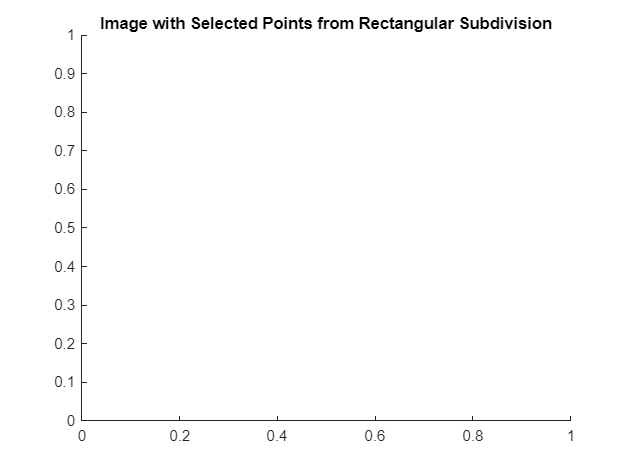

title('Image with Selected Points from Rectangular Subdivision');

function diffusedImg = EED(img, knownPoints, lambda, sigma, numIterations)
    [rows, cols] = size(img);
    diffusedImg = img;

    % Initialize the mask of known points
    mask = zeros(rows, cols);
    for i = 1:size(knownPoints, 1)
        mask(knownPoints(i, 1), knownPoints(i, 2)) = 1;
    end
    
    % Pre-smooth the image
    gaussFilter = fspecial('gaussian', ceil(6 * sigma), sigma);
    smoothImg = imfilter(diffusedImg, gaussFilter, 'replicate');
    
    for iter = 1:numIterations
        % Compute smoothed gradients
        [dx, dy] = gradient(smoothImg);
        gradientMagnitude = dx.^2 + dy.^2;

        % Compute the diffusion tensor components
        diffusivity = 1 ./ sqrt(1 + gradientMagnitude / lambda^2);
        diffX = diffusivity .* dx;
        diffY = diffusivity .* dy;

        % Divergence of the diffusion tensor
        divTerm = divergence(diffX, diffY);

        % Update only unknown pixels
        diffusedImg(~mask) = diffusedImg(~mask) + divTerm(~mask);
        
        % Update the smoothed version for the next iteration
        smoothImg = imfilter(diffusedImg, gaussFilter, 'replicate');
    end
end

% Example usage
lambda = 20;
sigma = 0.8;
numIterations = 50;
diffusedImg = EED(sparseImg, reconstructedPixelLocations, lambda, sigma, numIterations);

Unrecognized function or variable 'reconstructedPixelLocations'.

figure; imshow(uint8(diffusedImg)); title('Image after Edge-Enhancing Diffusion');

mseError = mean((diffusedImg(:) - originalImg(:)).^2)

mseError = 1.4649e+04

## UPDATED SUBDIVISION CODE 